# Color transfer between images

## Color transfer will transfer the color tone from the source image to the target image.

Step 1: Input images are a source and a target image.  Display both images.

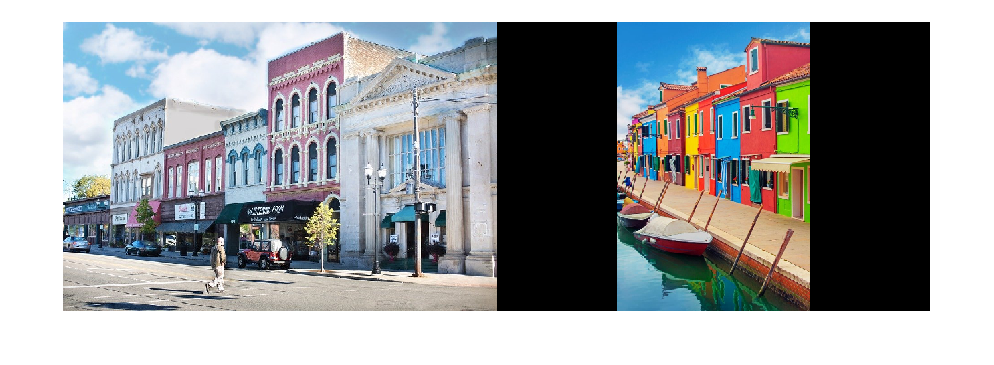

source = imread("city_block1.png");
target = imread("colorful_town1.png");
montage({source,target})

Step 2: Convert RGB to lαβ color space.  Images have size [m n 3].  You can use function "reshape" to change the size to [m*n  3]. So that we can multiply with other matrices.  

%Convert RGB to lαβ
%reshape to change the size
img_source = reshape(im2double(source),[],3);
img_target = reshape(im2double(target),[],3);

%fix the problem NaN
img_source = max(img_source,1/255);
img_target = max(img_target,1/255);

%convert to LMS
l = [0.3811 0.5783 0.0402;0.1967 0.7244 0.0782;0.0241 0.1288 0.8444];
LMS_source = l * img_source';
LMS_target = l * img_target';

%take log 
LMS_source = log10(LMS_source);
LMS_target = log10(LMS_target);

%convert to lαβ color space lab==lαβ
a = [1/sqrt(3) 0 0;0 1/sqrt(6) 0;0 0 1/sqrt(2)];
b = [1 1 1;1 1 -2;1 -1 0];
lab_source = a * b * LMS_source;
lab_target = a * b * LMS_target;

Step 3: Compute the mean and standard deviation of each of the lαβ channels for the source and target images.

%compute mean and std of source picture
mean_source_l = mean2(lab_source(1,:));
mean_source_a = mean2(lab_source(2,:));
mean_source_b = mean2(lab_source(3,:));

std_source_l = std2(lab_source(1,:));
std_source_a = std2(lab_source(2,:));
std_source_b = std2(lab_source(3,:));

%compute mean and std of target picture
mean_target_l = mean2(lab_target(1,:));
mean_target_a = mean2(lab_target(2,:));
mean_target_b = mean2(lab_target(3,:));

std_target_l = std2(lab_target(1,:));
std_target_a = std2(lab_target(2,:));
std_target_b = std2(lab_target(3,:));

Step 4: Subtract the mean of the lαβ channels of the target image from target channels.

target_channel_l = lab_target(1,:) - mean_target_l;
target_channel_a = lab_target(2,:) - mean_target_a;
target_channel_b = lab_target(3,:) - mean_target_b;

Step 5: Scale the target channels by the ratio of the standard deviation of the source divided by the standard deviation of the target, multiplied by the target channels.

target_channel_l = (std_source_l ./ std_target_l) .* target_channel_l;
target_channel_a = (std_source_a ./ std_target_a) .* target_channel_a;
target_channel_b = (std_source_b ./ std_target_b) .* target_channel_b;

Step 6: Add in the means of the lαβ channels for the source.

target_channel_l = mean_source_l + target_channel_l;
target_channel_a = mean_source_a + target_channel_a;
target_channel_b = mean_source_b + target_channel_b;
target_channel_lab = vertcat(target_channel_l,target_channel_a,target_channel_b);

Step 7: Convert lαβ back to RGB color space.

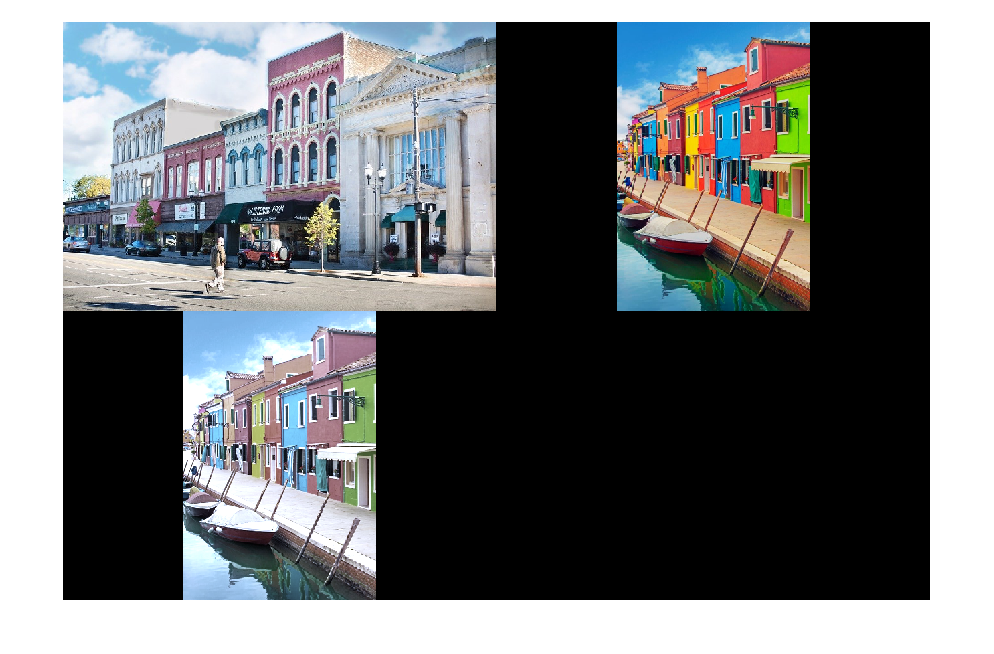

%convert to LMS
a1 = [1 1 1;1 1 -1;1 -2 0];
b1 = [sqrt(3)/3 0 0;0 sqrt(6)/6 0;0 0 sqrt(2)/2];
LMS_target_channel = a1 * b1 * target_channel_lab;
%convert to RGB
%number from slide 13
con = [4.4679 -3.5873 0.1193;-1.2186 2.3809 -0.1624;0.0497 -0.2439 1.2045];
final_img = (con * power(10,LMS_target_channel)); 
final_image = cat(3,final_img(1,:),final_img(2,:),final_img(3,:));
final_image1 = reshape(final_image,[720 480 3]);
montage({source,target,final_image1})